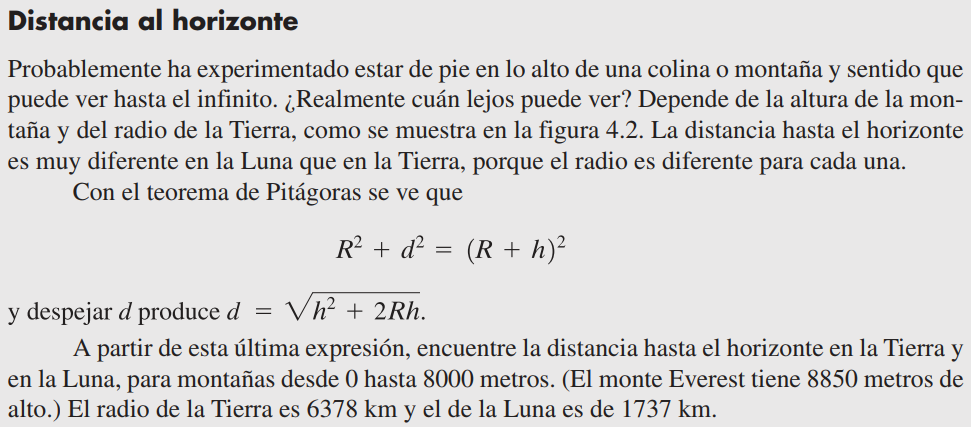

clear

% Definimos los datos conocidos.
h = 0:1000:8000';
r = [6378e3 1737e3];

% Se relacionan las variables.
[new_r, new_h] = meshgrid(r,h);
Rh = new_r .* new_h

Rh = 	1.0e+10 *

         0         0
    0.6378    0.1737
    1.2756    0.3474
    1.9134    0.5211
    2.5512    0.6948
    3.1890    0.8685
    3.8268    1.0422
    4.4646    1.2159
    5.1024    1.3896


% Aplicamos la ecuación de la distancia.
d1 = sqrt(h'.^2 + 2*Rh);     % Distancia en m.
d2 = array2table(d1/1000,"VariableNames", ...
    {'d (km) con radio de la Tierra','d (km) con radio de la Luna'})

d2 = 9×2 table
    d (km) con radio de la Tierra    d (km) con radio de la Luna
    _____________________________    ___________________________

                    0                               0           
               112.95                          58.949           
               159.74                          83.379           
               195.65                          102.13           
               225.92                          117.95           
                252.6                          131.89           
               276.72                           144.5           
                298.9                           156.1           
               319.55                           166.9           


% d2 muestra las distancias en km.